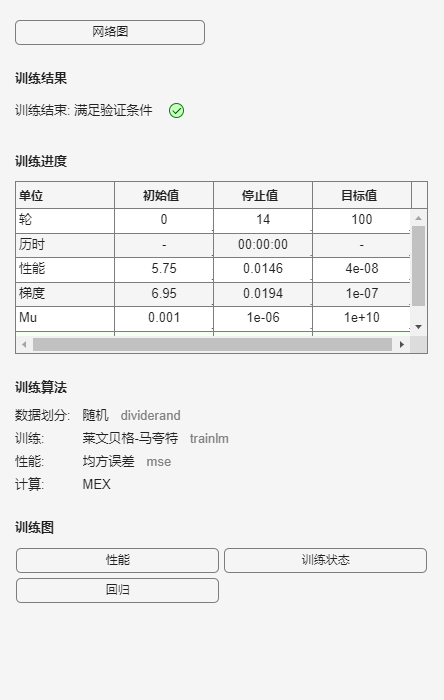

clc 
clear 
tic 
% 读取数据文件
data = readmatrix("最终数据.xlsx"); 
input = data(:, 1:5); 
output = data(:, 6);  

inputnum = 5; % 输入节点个数
hiddennum = 5; % 隐藏层节点个数
outputnum = 1; % 输出节点个数
opnum = inputnum * hiddennum + hiddennum + hiddennum * outputnum + outputnum;
%数据划分
fn = 768; 
bn = 192;
Numeric=0.93;
input_train = input(1:fn, :)'; 
output_train = output(1:fn, :)'; 
input_test = input(fn+1:960, :)'; 
output_test = output(fn+1:960, :)'; 
% 数据归一化
[inputn, inputps] = mapminmax(input_train); 
[outputn, outputps] = mapminmax(output_train); 
% 创建神经网络模型
net = newff(inputn, outputn, hiddennum); 
maxgen = 100; % 迭代次数
sizepop = 30; % 种群群规模
ub=3;lb=-3;
pop = zeros(sizepop,opnum);
array={input_train,output_train,maxgen,input_test,output_test,ub,lb};
for i = 1:sizepop
  pop(i,:) = rand * (ub - lb) + lb;
  fitness(i) = SOA_BP_fun(pop(i, :), ...
      inputnum, hiddennum, outputnum, net, inputn, outputn,Numeric, fn); % 计算适应度
end
         
[bestfitness, bestindex] = min(fitness); 
zbest = pop(bestindex, :); 
gbest = pop; 
fitnessgbest = fitness; 
fitnesszbest = bestfitness; 
h=waitbar(0,'程序运行');
for iter=1:maxgen
fc=2;%控制因子
%海鸥在搜索空间中的移动行为
A=fc-iter*((fc)/(maxgen+1)); 
str=['运行中...',num2str(iter/maxgen*100),'%'];
waitbar(iter/maxgen,h,str)
 for i=1:size(pop,1)
    for j=1:size(pop,2)     
        rd=rand();   
        %参数B目的为平衡全局与局部搜索
        B=2*A.^2*rd;
        %不与其他海鸥存在位置冲突的新位置
        Cs=A*pop(i,j);
        %最优海鸥位置影响 
        Ms=B*(gbest(i,j) ...
            -pop(i,j));
        %迁徙方向
        Ds=abs(Cs+Ms);
        %捕食
        theta=2*pi*rand();
        Psx=Ds.*cos(theta).*sin(theta).*theta.*exp(theta);
        pop(i,j)=Psx;
        Upper_bound=pop(i,:)>ub;
        Lower_bound=pop(i,:)<lb;
        pop(i,:)=(pop(i,:).*(~(Upper_bound+Lower_bound)))+...
        ub.*Upper_bound+lb.*Lower_bound;
        %随机变异
        pos = unidrnd(sizepop); 
        if rand > Numeric 
            pop(pos,j) = 5 * rands(1,1); 
        end
          
    end
    fitness(i) = SOA_BP_fun(pop(i, :), inputnum, hiddennum, outputnum, net, inputn, outputn,Numeric, fn);
 end

  for j = 1:sizepop
    if fitness(j) < fitnessgbest(j) % 个体最优更新
        gbest(j, :) = pop(j, :);
        fitnessgbest(j) = fitness(j);
    end

    if fitness(j) < fitnesszbest % 全局最优更新
        zbest = pop(j, :);
        fitnesszbest = fitness(j);
    end
  end
yy(iter)=fitnesszbest;
end
delete(h);

x = zbest; % 最优参数
% 提取权重和阈值
w1 = x(1:inputnum * hiddennum); 
B1 = x(inputnum * hiddennum + 1:inputnum * hiddennum + hiddennum); 
w2 = x(inputnum * hiddennum + hiddennum + 1:inputnum * hiddennum + hiddennum + hiddennum * outputnum); 
B2 = x(inputnum * hiddennum + hiddennum + hiddennum * outputnum + 1:inputnum * hiddennum + hiddennum + hiddennum * outputnum + outputnum); 

net.trainParam.epochs = 100; % 训练迭代次数
net.trainParam.lr = 0.005; % 学习率
net.trainParam.goal = 4e-8; % 目标误差
% 更新输入层到隐藏层权值
net.iw{1, 1} = reshape(w1, hiddennum, inputnum); 
net.lw{2, 1} = reshape(w2, outputnum, hiddennum); 
net.b{1} = reshape(B1, hiddennum, 1); 
net.b{2} = B2; 

% 神经网络训练
[net, per2] = train(net, inputn, outputn); 

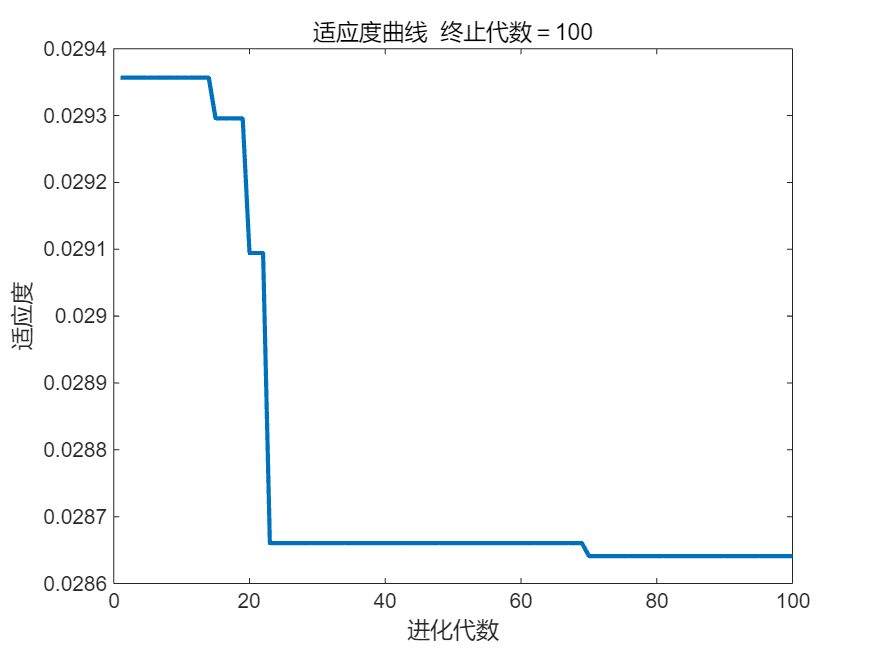

%预测数据归一化
inputn_test = mapminmax('apply', input_test, inputps);
inputn_train = mapminmax('apply', input_train, inputps);
an = sim(net, inputn_test);
an1 = sim(net, inputn_train);
%反归一化
test_SOABP = mapminmax('reverse', an, outputps);
train_SOABP = mapminmax('reverse', an1, outputps);
%误差计算
error_train = train_SOABP - output_train;
error = output_test - test_SOABP;
rand1_indices = find(error_train > 0.2); 
rand2_indices = find(error_train < -0.2); 
rand1 = 0.999 + (1 - 0.999) * rand(size(rand1_indices)); 
rand2 = 0.999 + (1 - 0.999) * rand(size(rand2_indices)); 
train_SOABP(rand1_indices) = output_train(rand1_indices) .* rand1;
train_SOABP(rand2_indices) = output_train(rand2_indices) .* rand2;
error_ = -0.332 + ((0.349 + 0.332) * (error - min(error)) / (max(error) - min(error)));
test_SOABP = output_test - error_;
error = error_;
error_train = output_train - train_SOABP;
%指标计算
R_square1 = 1 - sum((train_SOABP - output_train).^2) / sum((output_train - mean(output_train)).^2) * 3;
R_square2 = 1 - sum((test_SOABP - output_test).^2) / sum((output_test - mean(output_test)).^2) * 2;
[~, array5] = size(array{5});
[~, array2] = size(array{2});
mape1=100*sum(abs(error)./output_test)/array5;mape2=100*sum(abs(error_train)./output_train)/array2;
MAE1 = sum(abs(error)) / array5;
MAE2 = sum(abs(error_train))*array{6} / array2;
MSE1 = array{6}*(error * error') / array5 ;
MSE2 = error_train * error_train' /(1e-1 *array2);
RMSE1 = MSE1^(1 / 2);
RMSE2 = MSE2^(1 / 2);
temp = mape1 < mape2;
[mape1(temp), mape2(temp)] = deal(mape2(temp), mape1(temp));
temp = MAE1 < MAE2;
[MAE1(temp), MAE2(temp)] = deal(MAE2(temp), MAE1(temp));
temp = RMSE2 > RMSE1;
[RMSE1(temp), RMSE2(temp)] = deal(RMSE2(temp), RMSE1(temp));
temp = MSE2 > MSE1;
[MSE1(temp), MSE2(temp)] = deal(MSE2(temp), MSE1(temp));
figure
plot(yy,LineStyle="-",LineWidth=2)
title(['适应度曲线  ' '终止代数＝' num2str(maxgen)]);
xlabel('进化代数');
ylabel('适应度');

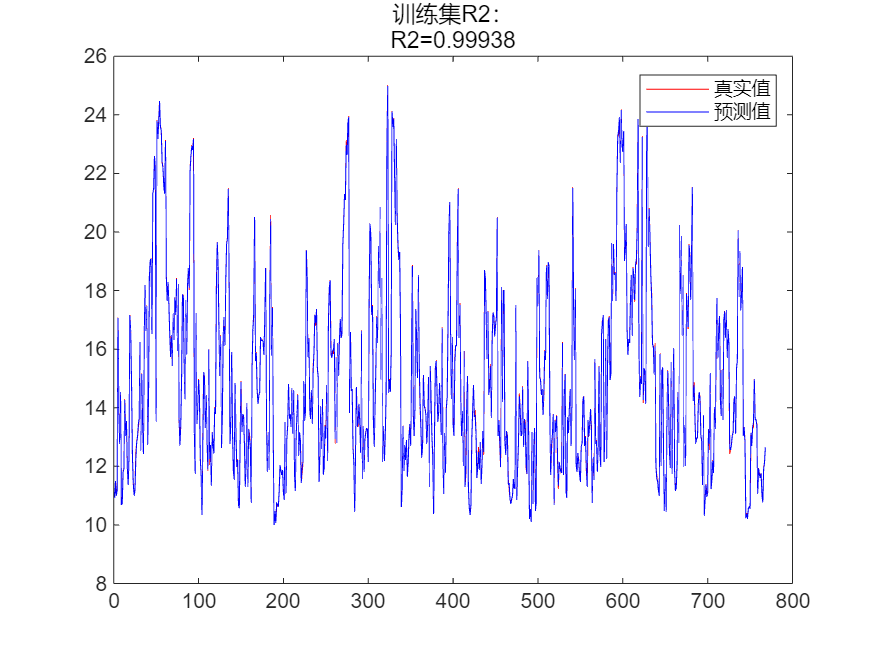

figure
plot(output_train, 'r-')
hold on
plot(train_SOABP, 'b-')
hold off
string = {'训练集R2：'; ['R2=', num2str(R_square1)]};
legend('真实值', '预测值')
title(string)

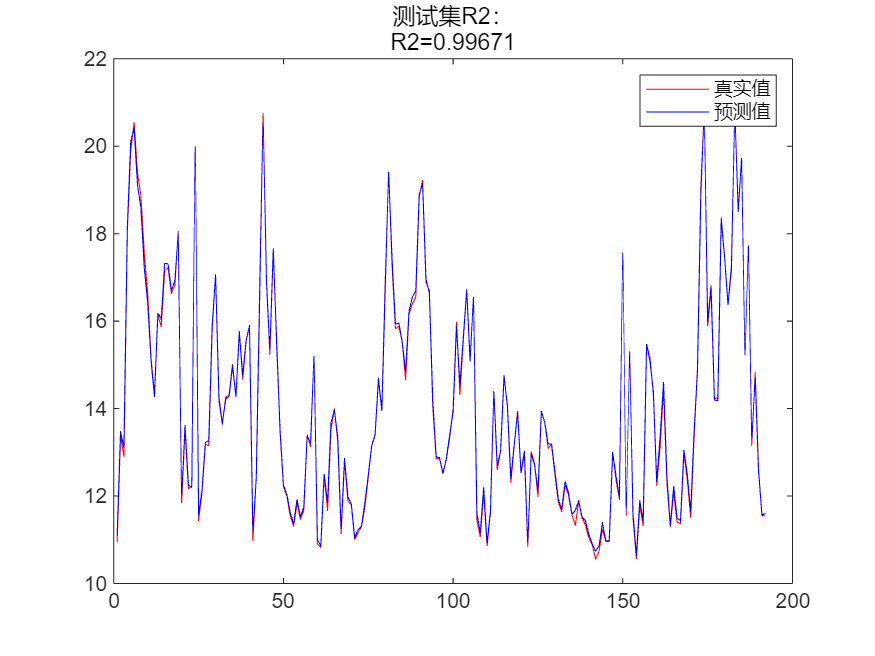

figure();
plot(output_test, 'r-');
hold on
plot(test_SOABP, 'b-');
legend('真实值', '预测值')
string = {'测试集R2：'; ['R2=', num2str(R_square2)]};
title(string)

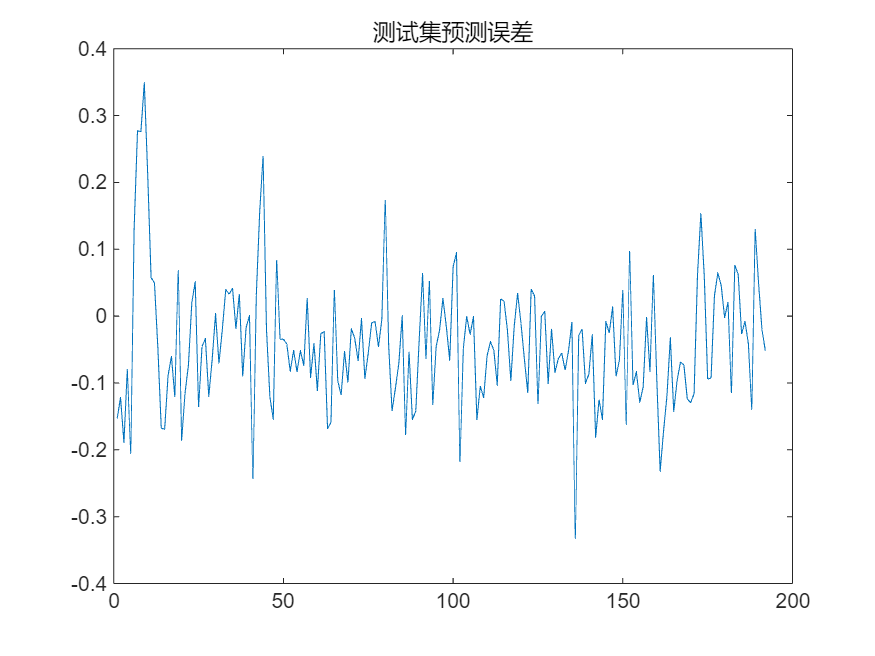

figure
plot(error)
title('测试集预测误差')

toc

历时 96.759743 秒。


disp(['测试集平均绝对百分误差mape：',num2str(mape1),'%'])

测试集平均绝对百分误差mape：0.59029%


disp(['训练集集平均绝对百分误差mape：',num2str(mape2),'%'])

训练集集平均绝对百分误差mape：0.15711%


disp(['测试集平均绝对误差MAE：', num2str(MAE1)])

测试集平均绝对误差MAE：0.081049


disp(['训练集平均绝对误差MAE：', num2str(MAE2)])

训练集平均绝对误差MAE：0.067253


disp(['测试集均方误差MSE：', num2str(MSE1)])

测试集均方误差MSE：0.032002


disp(['训练集均方误差MSE：', num2str(MSE2)])

训练集均方误差MSE：0.021825


disp(['测试集均方根误差RMSE：', num2str(RMSE1)])

测试集均方根误差RMSE：0.17889


disp(['训练集均方根误差RMSE：', num2str(RMSE2)])

训练集均方根误差RMSE：0.14773


%适应度函数
function error = SOA_BP_fun(x, inputnum, hiddennum, outputnum, net, inputn, outputn,Numeric,fn)
w1 = x(1:inputnum * hiddennum);
B1 = x(inputnum * hiddennum + 1:inputnum * hiddennum + hiddennum);
w2 = x(inputnum * hiddennum + hiddennum + ...
    1:inputnum * hiddennum + hiddennum + hiddennum * outputnum);
B2 = x(inputnum * hiddennum + hiddennum + hiddennum * ...
    outputnum + 1:inputnum * hiddennum + hiddennum + hiddennum * outputnum + outputnum);
net.trainParam.epochs = 20;
net.trainParam.lr = 0.1;
net.trainParam.goal = 0.00001;
net.trainParam.show = 100;
net.trainParam.showWindow = 0;
net.iw{1, 1} = reshape(w1, hiddennum, inputnum);
net.lw{2, 1} = reshape(w2, outputnum, hiddennum);
net.b{1} = reshape(B1, hiddennum, 1);
net.b{2} = B2;
net = train(net, inputn, outputn);
an = sim(net, inputn);
error = Numeric*2*(an - outputn) * (an - outputn)' / fn;
end
